Question 2

a) generate data and plot on same graph

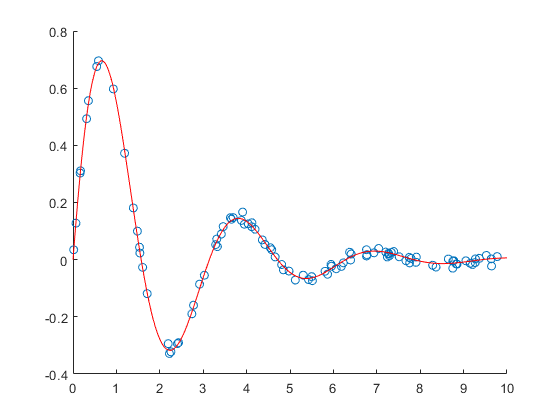

clearvars
A = zeros(1,100);
xi = 10*rand(1,100);
f = @(x) (exp(-x/2).*sin(2.*x));
w = f(xi);
for i=1:100
    A(1,i) = f(xi(i)) + randn*10^(-2);
end
hold on
scatter(xi,A);
x = 0:0.05:10;
y = f(x);
plot(x,y,'r')
hold off

Blue circles are generated data points agains red line showing optimal function

b)calculate for c value with initial c0 = [1.1; 0.4; 1.9; 0]

GaussNewton(xi,A, [1.1; -0.4; 1.9; 0])

ans =    1.000894066011380
  -0.500606774032169
   1.999687523357157
   0.000844730205554


the final value will be slightly off from the optimal value of [1; -0.5; 2; 0] considering the pertubation added but it still converges. With smaller pertubation, final c value is closer to optimal c.

c) starting [1; 1; 1; 1] will not lead to convergence leading to badly scaled matrix

GaussNewton(xi,A, [1; 1; 1; 1])

ans =    NaN
   NaN
   NaN
   NaN


will not result convergence.